clc; clear all;
data = readtable("hr_with_i2cDMA", 'Format', "%s", 'ReadVariablenames', false, "Delimiter", "comma");
ir_vals = [];
red_vals = [];
sound_vals = [];

% skip first row
for i=2:length(data.Var1)
    token_array = regexp(data.Var1(i), ".* -> [A-z :]*(-?\d*)", 'tokens');
    token = token_array{1};
    num = str2double(token{1});
    if ~isnan(num)
        if contains(data.Var1(i), "IR VAL:")
            ir_vals = [ir_vals, num];
           
        elseif contains(data.Var1(i), "RED VAL:")
            red_vals = [red_vals, num];
        else
            sound_vals = [sound_vals, num];
        end
    end
end

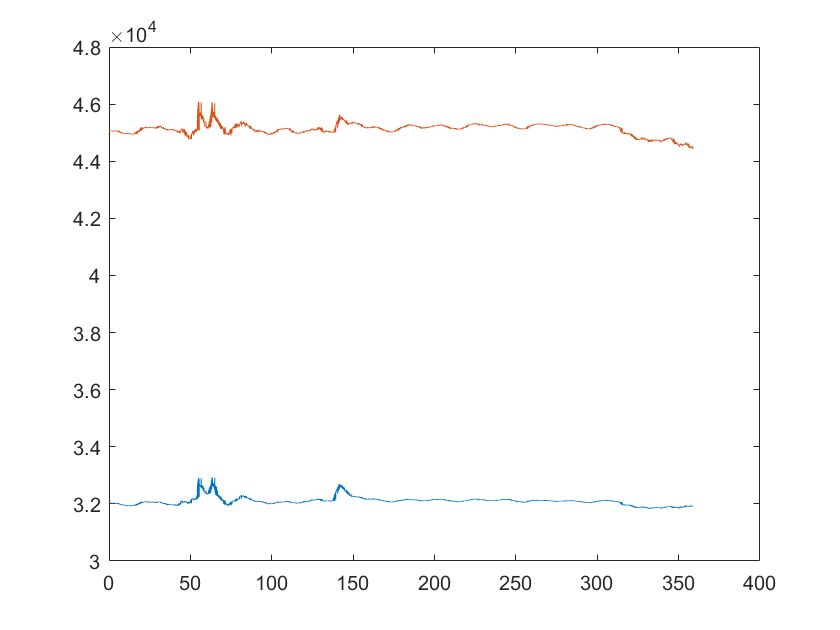

Hr_time=linspace(0,length(red_vals)*0.047,length(red_vals));
sound_time= linspace(0,length(sound_vals)*0.004462,length(sound_vals)); 
figure
plot(Hr_time, red_vals);
hold on
plot(Hr_time, ir_vals);
hold off

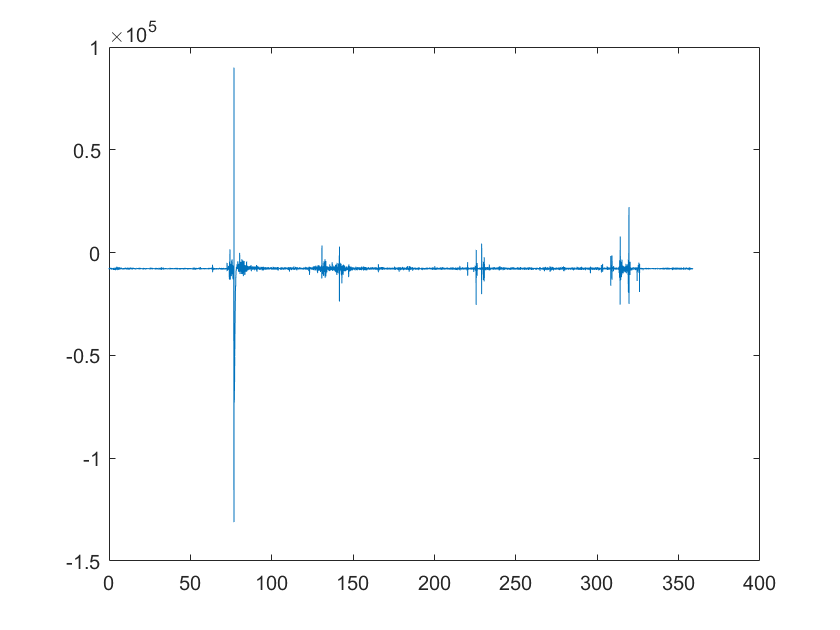

figure
plot(sound_time, sound_vals);

The reason why we are doing linspace is to create artifical time array to plot our values.

Basing it off the HR array (1x7633 double) and we are assuming time ticks of 0.01s, we can calculate the length of the sample we are

taking which is going to be $\mathrm{length}\;\mathrm{time}\;\mathrm{of}\;\mathrm{sample}=\mathrm{Length}\;\mathrm{of}\;\mathrm{array}\;\left(7633\right)*\;\mathrm{timestep}\;\left(0\ldotp 01\right)=76\ldotp 3\;\mathrm{seconds}$

To create the same time for the sound, we need to determine the sound timestep which can be found by


$$\mathrm{sound}{\;}_{\mathrm{time}\;\mathrm{step}} =\frac{\mathrm{length}\;\mathrm{of}\;\mathrm{time}\;\mathrm{sample}}{\;\mathrm{array}\;\mathrm{length}\;\mathrm{of}\;{\mathrm{sound}}_{\mathrm{vals}} }=\frac{76\ldotp 3}{80400}=0\ldotp 000949\;s$$
